#  ECSE 343: Numerical Methods in Engineering

#  Assignment 3

Due Date: 23rd March 2023

Student Name: Simon Li    

Student ID:    260984998

Please type your answers and write you code in this .mlx script. If you choose to provide the handwritten answers, please scan your answers and include those in SINGLE pdf file.

Please submit this **.mlx** file along with the **PDF** copy of this file.

Note: Make sure that the you have downloaded the data file named* q1_refSol.mat. *You must store the data file in the smae directory as the Assignment 3 file.

## Question 1:  

You are given the following 3rd order differential equation,

                
$$y^{'''}(t) + 32 y^{''} (t) +61.25 y'(t)  + 37.5 y(t)  = sin(t/4)$$


a. Transform the above differential equation into a system of first-order differential equations. **(5 marks)**

*        % Show all your work here. Write all your steps and equations.*

define the following variables:

- y₁(t) = y(t)

- y₂(t) = y'(t)

- y₃(t) = y''(t)

Now we can write the first-order differential equations for each variable:

- y₁'(t) = y₂(t)

- y₂'(t) = y₃(t)

- y₃'(t) = y'''(t)

We are given the 3rd order differential equation:

y'''(t) + 32y''(t) + 61.25y'(t) + 37.5y(t) = sin(t/4)

Substitute the new variables into the original equation:

y₃'(t) + 32y₃(t) + 61.25y₂(t) + 37.5y₁(t) = sin(t/4)

Now, we can isolate y₃'(t):

y₃'(t) = -32y₃(t) - 61.25y₂(t) - 37.5y₁(t) + sin(t/4)

Finally, we have the system of first-order differential equations:

- y₁'(t) = y₂(t)

- y₂'(t) = y₃(t)

- y₃'(t) = -32y₃(t) - 61.25y₂(t) - 37.5y₁(t) + sin(t/4)

b.  For the system of first order ODEs obtained in part a, apply the Backward Euler approximation for the derivative and write the obtained **difference Equations **below. **(5 marks)**

*        % type your answer here, write all the equations*

general formula for the Backward Euler method is:

y'(t) ≈ (y(t + h) - y(t)) / h

where h is the time step size. Now, we'll apply this approximation to the system of first-order differential equations obtained in part a:

- y₁'(t) = y₂(t)

- y₂'(t) = y₃(t)

- y₃'(t) = -32y₃(t) - 61.25y₂(t) - 37.5y₁(t) + sin(t/4)

Applying the Backward Euler approximation to each equation:

- (y₁(t + h) - y₁(t)) / h ≈ y₂(t + h)

- (y₂(t + h) - y₂(t)) / h ≈ y₃(t + h)

- (y₃(t + h) - y₃(t)) / h ≈ -32y₃(t + h) - 61.25y₂(t + h) - 37.5y₁(t + h) + sin((t + h)/4)

Now, we can rearrange the equations to isolate the function values at t + h:

- y₁(t + h) ≈ y₁(t) + h * y₂(t + h)

- y₂(t + h) ≈ y₂(t) + h * y₃(t + h)

- y₃(t + h) ≈ y₃(t) + h * (-32y₃(t + h) - 61.25y₂(t + h) - 37.5y₁(t + h) + sin((t + h)/4))

These are the difference equations for the system of first-order ODEs using the Backward Euler approximation.

c.  You are provided with the initial conditions, $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$ for the given differential equation.  Use the cell below to implement the Backward Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  

Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**


clear all
dT = 0.065; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.

% Initial conditions
y1 = zeros(1, length(T));
y2 = zeros(1, length(T));
y3 = zeros(1, length(T));

y1(1) = 0;
y2(1) = 1;
y3(1) = 0;

% Backward Euler method
for i = 1:length(T)-1
    t = T(i);
    fun = @(Y) [Y(1) - y1(i) - dT * Y(2);...
                Y(2) - y2(i) - dT * Y(3);...
                Y(3) - y3(i) - dT * (-32*Y(3) - 61.25*Y(2) - 37.5*Y(1) + sin((t+dT)/4))];
    Y = fsolve(fun, [y1(i), y2(i), y3(i)]);
    y1(i+1) = Y(1);
    y2(i+1) = Y(2);
    y3(i+1) = Y(3);
end



%------------------------------------------------------------------------------
load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y1,'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

d.  Run the code you wrote in part c again, run the code for $25s$ and use the time step $\Delta t= 1s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

 Is the obtained solution more accurate than the solution in part c? Explain.  **(2 marks)**

*Note: You may copy the code you wrote in part c in the cell below to run it for *$\Delta t =1s$ 

% you may copy the code from part c here and run it for deltaT =1s
clear all
dT = 1; %sec
T = 0:dT:25;

% Initial conditions
y1 = zeros(1, length(T));
y2 = zeros(1, length(T));
y3 = zeros(1, length(T));

y1(1) = 0;
y2(1) = 1;
y3(1) = 0;

% Backward Euler method
for i = 1:length(T)-1
    t = T(i);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

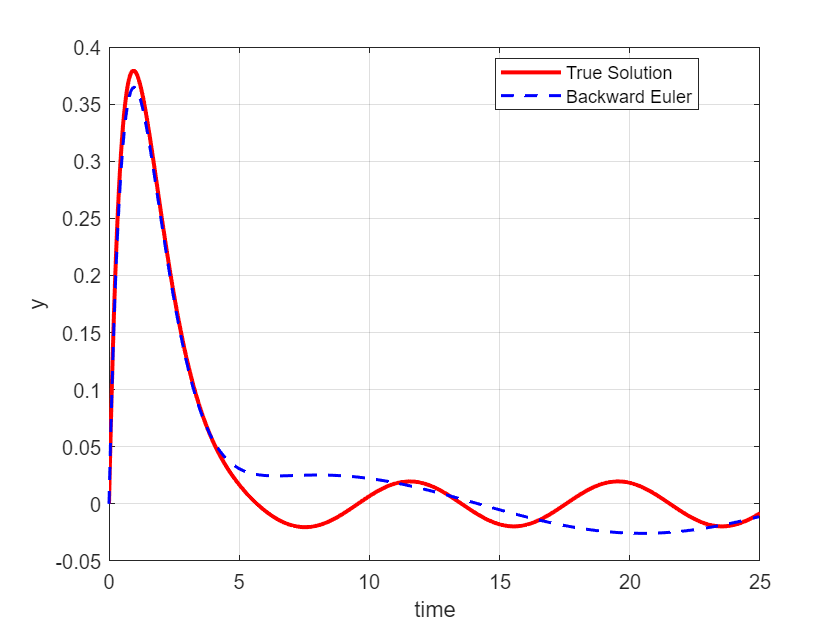

    fun = @(Y) [Y(1) - y1(i) - dT * Y(2);...
                Y(2) - y2(i) - dT * Y(3);...
                Y(3) - y3(i) - dT * (-32*Y(3) - 61.25*Y(2) - 37.5*Y(1) + sin((t+dT)/4))];
    Y = fsolve(fun, [y1(i), y2(i), y3(i)]);
    y1(i+1) = Y(1);
    y2(i+1) = Y(2);
    y3(i+1) = Y(3);
end

load('q1_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q1_Tref,Q1_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 

% plot your solution here.
plot(T, y1, 'b--', 'LineWidth', 1.5, 'displayname', 'Backward Euler')

xlabel('time')
ylabel('y')
grid on
legend("Location","best")

*% type your answer here*

*It's not as accurate. W*hen using numerical methods like the Backward Euler method, a smaller time step (dT) results in a more accurate solution.

e. For the system of first-order ODEs obtained in part a, use the Forward Euler approximation for the derivative and write the obtained difference Equations below. **(5 marks)**

*        %  type your answer here. Show all the equations and steps.*

general formula for the Forward Euler method is:

y'(t) ≈ (y(t + h) - y(t)) / h

where h is the time step size. Now, we'll apply this approximation to the system of first-order differential equations obtained in part a:

- y₁'(t) = y₂(t)

- y₂'(t) = y₃(t)

- y₃'(t) = -32y₃(t) - 61.25y₂(t) - 37.5y₁(t) + sin(t/4)

Applying the Forward Euler approximation to each equation:

- (y₁(t + h) - y₁(t)) / h ≈ y₂(t)

- (y₂(t + h) - y₂(t)) / h ≈ y₃(t)

- (y₃(t + h) - y₃(t)) / h ≈ -32y₃(t) - 61.25y₂(t) - 37.5y₁(t) + sin(t/4)

Now, we can rearrange the equations to isolate the function values at t + h:

- y₁(t + h) ≈ y₁(t) + h * y₂(t)

- y₂(t + h) ≈ y₂(t) + h * y₃(t)

- y₃(t + h) ≈ y₃(t) + h * (-32y₃(t) - 61.25y₂(t) - 37.5y₁(t) + sin(t/4))

These are the difference equations for the system of first-order ODEs using the Forward Euler approximation.

f. Use the same initial conditions as part c (i.e. $y(0) =0$, $y'(0) =1$, and  $y''(0) = 0$).  Implement the Forward  Euler method to solve the first order ODE's obtained in part a . Run the simulation for $25s$, use the time step $\Delta t= 0.065s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution, label your plots appropriately. **(5 marks)**

Write your code in the cell below.

clear all
dT = 0.065; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.
% Initial conditions
y1 = zeros(1, length(T));
y2 = zeros(1, length(T));
y3 = zeros(1, length(T));

y1(1) = 0;
y2(1) = 1;
y3(1) = 0;

% Forward Euler method
for i = 1:length(T)-1
    t = T(i);
    y1(i+1) = y1(i) + dT * y2(i);
    y2(i+1) = y2(i) + dT * y3(i);
    y3(i+1) = y3(i) + dT * (-32*y3(i) - 61.25*y2(i) - 37.5*y1(i) + sin(t/4));
end

%------------------------------------------------------------------------------


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

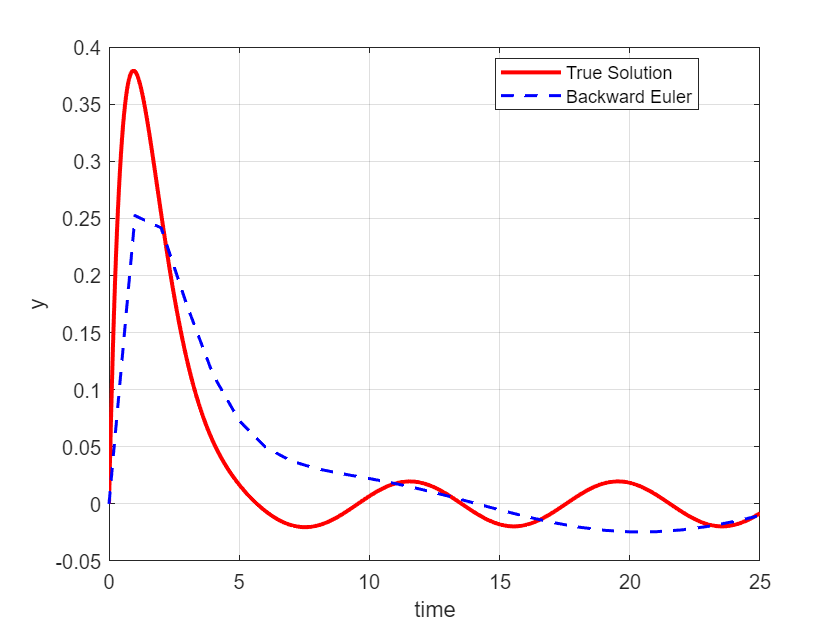

load('q2_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q2_Tref,Q2_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison
hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              

xlabel('time')
ylabel('y')
grid on
legend("Location","best")

g. Run the code you wrote in part f again, run the code for $25s$ and use the time step $\Delta t= 0.068s$.  Plot  $y(t)$ vs $t$ on the same plot as the true solution.

*Note: You may copy the code you wrote in part f in the cell below to run it for *$\Delta t =0.068s$ 

Comment on the solutions obtained in part e and f. **(2 marks)**

% you may copy the code from part c here and run it for deltaT =1s
clear all
dT = 0.068; %sec
T = 0:dT:25; 

%-----------------------------------------------------------------------------
% write the your code here.
% Initial conditions
y1 = zeros(1, length(T));
y2 = zeros(1, length(T));
y3 = zeros(1, length(T));

y1(1) = 0;
y2(1) = 1;
y3(1) = 0;

% Forward Euler method
for i = 1:length(T)-1
    t = T(i);
    y1(i+1) = y1(i) + dT * y2(i);
    y2(i+1) = y2(i) + dT * y3(i);
    y3(i+1) = y3(i) + dT * (-32*y3(i) - 61.25*y2(i) - 37.5*y1(i) + sin(t/4));
end

%------------------------------------------------------------------------------
% load('q2_refSol.mat') % load true analytical sol for reference.

figure()
plot(Q2_Tref,Q2_ref_sol,'r-','LineWidth',2,'displayname','True Solution') % plots true solution for comparison

Unrecognized function or variable 'Q2_Tref'.

hold on 
%-------------------------------------------------------------------------------


% plot your solution here.
plot(T,y,'b--','LineWidth',1.5,'displayname','Backward Euler')
% Note: the variable y is the y(t).  You may choose to rename it according
% to your preference,.                                        
%--------------------------------------------------------------------------------                                                              
                                                              
xlabel('time')
ylabel('y')
grid on
legend("Location","best")

*% you can type  your comments  here.*

the Forward Euler method is less accurate and less stable than the Backward Euler method, especially when using larger time steps. This is because the Forward Euler method uses the current state information to estimate the next state, while the Backward Euler method implicitly solves for the next state, making it more stable.

h. In the  lecture, we discussed how the poles of a first-order system of ODE equations can be used to determine the step size for which the Forward Euler is stable. Using the poles of the system you obtained in part a, find the largest step size, $\Delta t$, for which the Forward Euler method is stable. Show all your equations. **(6 marks)**

*% you can type  your solution here.*

dY/dt = AY + F(t), where Y = [y₁(t), y₂(t), y₃(t)]' and A is a 3x3 matrix.

The matrix A for our system is:

A = [ 0 1 0 ; 0 0 1 ; -37.5 -61.25 -32 ]

The poles of the system are the eigenvalues of matrix A. We can find the eigenvalues using the characteristic equation:

det(A - λI) = 0

where I is the identity matrix and λ is an eigenvalue. The characteristic equation for our matrix A is:

λ³ + 32λ² + 61.25λ + 37.5 = 0

A = [0, 1, 0; 0, 0, 1; -37.5, -61.25, -32];
eigenvalues = eig(A)

eigenvalues =  -30.0000 + 0.0000i
  -1.0000 + 0.5000i
  -1.0000 - 0.5000i


To find the largest step size for which the Forward Euler method is stable, we need to consider the stability region of the Forward Euler method, which is a left half-plane in the complex plane:

Re(1 + hλ) < 1

where h is the step size and λ is a pole (eigenvalue) of the system. To ensure stability, this condition must be satisfied for all eigenvalues (poles) of the system.

Given the complexity of the characteristic equation, it is best to solve for the eigenvalues numerically. Once we have the eigenvalues, we plug them into the stability condition:

Re(1 + hλ) < 1

and solve for the largest step size h that satisfies this condition for all eigenvalues:

Re(1 + hλ) < 1

Let's check each eigenvalue:

- λ₁ = -30 + 0i

Re(1 + hλ₁) = Re(1 - 30h) < 1

1 - 30h < 1

-30h < 0

h > 0

- λ₂ = -1 + 0.5i

Re(1 + hλ₂) = Re(1 - h + 0.5hi) < 1

1 - h < 1

-h < 0

h > 0

- λ₃ = -1 - 0.5i

Re(1 + hλ₃) = Re(1 - h - 0.5hi) < 1

1 - h < 1

-h < 0

h > 0

Since all eigenvalues are in the left half-plane, the Forward Euler method will be stable for any positive step size h.